clc 
close all
clear 

## start

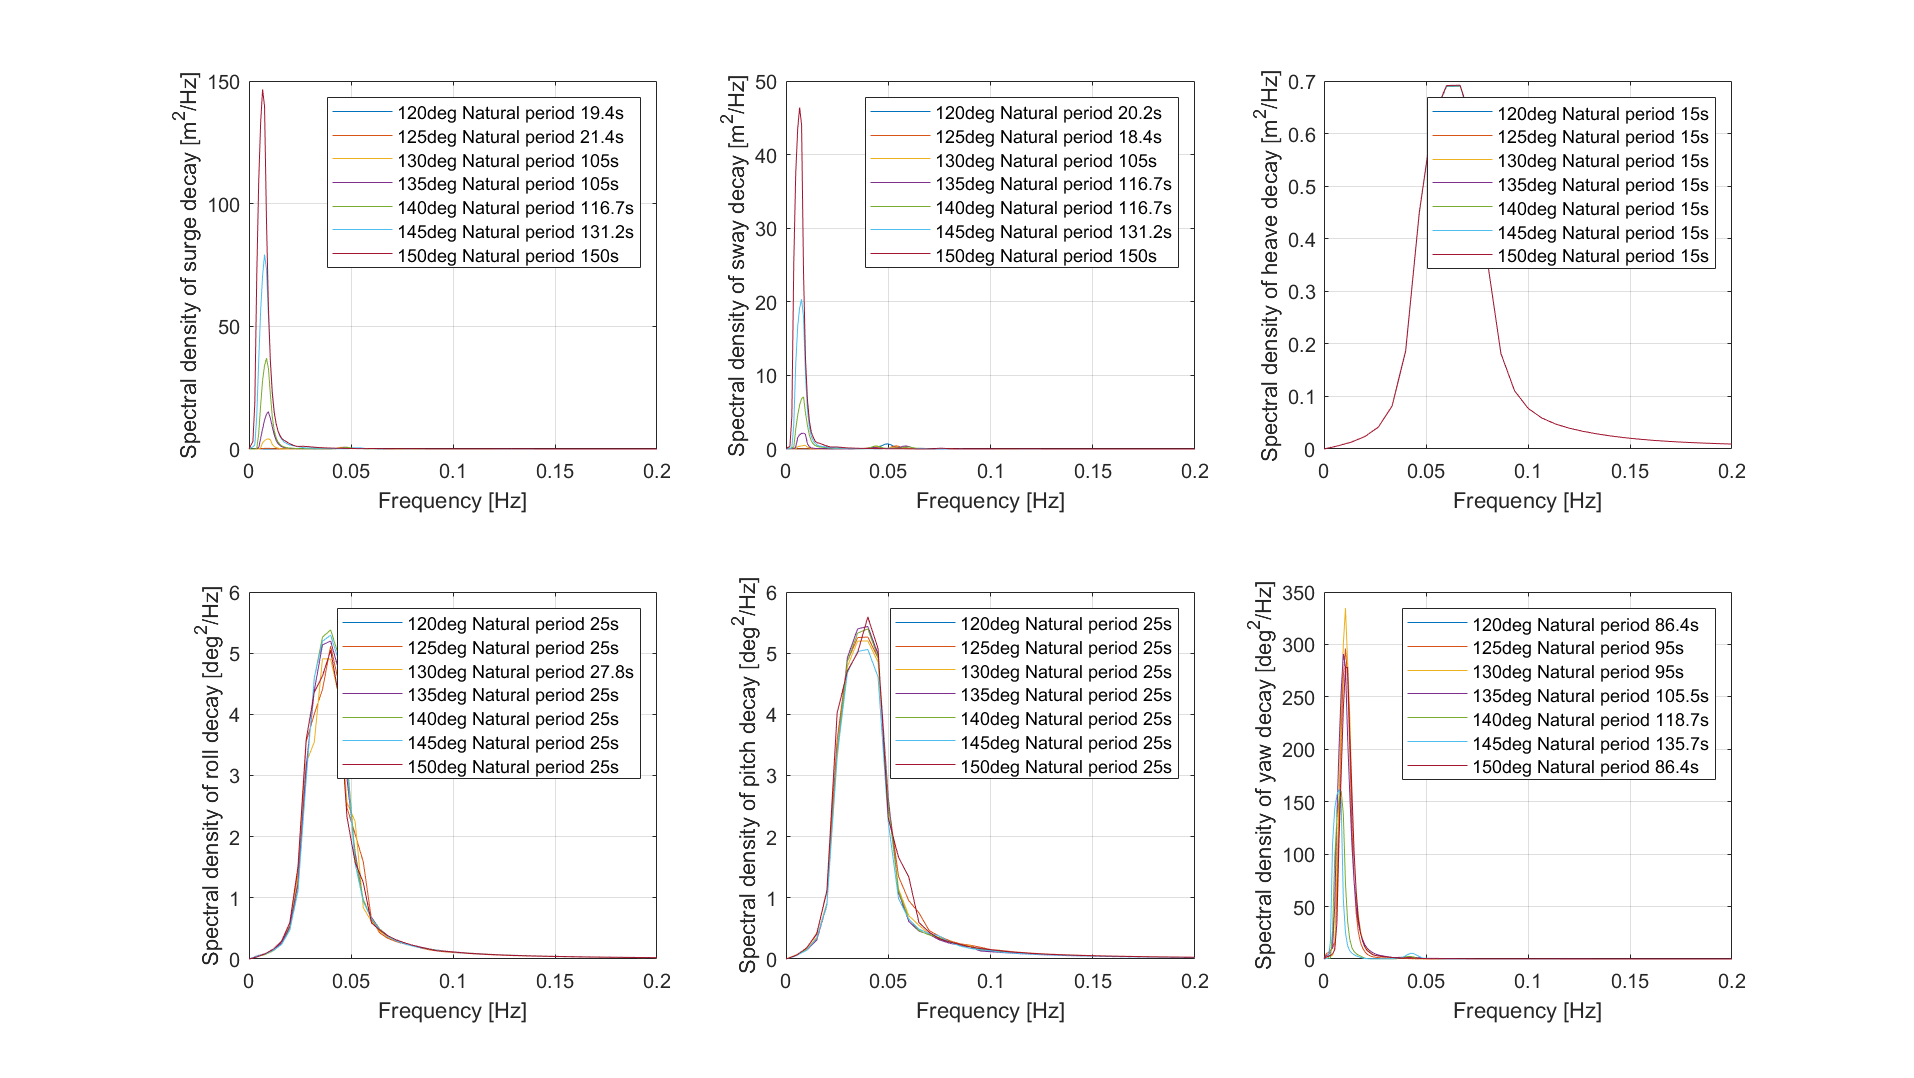


base='E:\MatlabFiles\DecayResults/Decays_';
loadnames=[base '120.mat';base '125.mat';base '130.mat';base '135.mat';base '140.mat';base '145.mat';base '150.mat'];
   fpsds_F1=zeros(7,10500);
    fpsds_F2=zeros(7,10500);
    fpsds_F3=zeros(7,1500);
    fpsds_M1=zeros(7,2500);
    fpsds_M2=zeros(7,2000);
    fpsds_M3=zeros(7,9500);
    psds_F1=zeros(7,10500);
    psds_F2=zeros(7,10500);
    psds_F3=zeros(7,1500);
    psds_M1=zeros(7,2500);
    psds_M2=zeros(7,2000);
    psds_M3=zeros(7,9500);
for i=1:7
    load (loadnames(i,:));
    fpsds_F1(i,:)=fpsd_F1;
    fpsds_F2(i,:)=fpsd_F2;
    fpsds_F3(i,:)=fpsd_F3;
    fpsds_M1(i,:)=fpsd_M1;
    fpsds_M2(i,:)=fpsd_M2;
    fpsds_M3(i,:)=fpsd_M3;
    psds_F1(i,:)=smooth(psd_F1);
    psds_F2(i,:)=smooth(psd_F2);
    psds_F3(i,:)=smooth(psd_F3);
    psds_M1(i,:)=smooth(psd_M1);
    psds_M2(i,:)=smooth(psd_M2);
    psds_M3(i,:)=smooth(psd_M3);
end

N=7;
NatPerF1 = cell(N,0);
NatPerF2 = cell(N,0);
NatPerF3 = cell(N,0);
NatPerM1 = cell(N,0);
NatPerM2 = cell(N,0);
NatPerM3 = cell(N,0);
for k=1:7
[max_num,loc]=max(psds_F1(k,:));
tmp=num2cell(round(1/fpsd_F1(loc),1));
NatPerF1(k,1:numel(tmp)) = tmp;

[max_num,loc]=max(psds_F2(k,:));
tmp=num2cell(round(1/fpsd_F2(loc),1));
NatPerF2(k,1:numel(tmp)) = tmp;

[max_num,loc]=max(psds_F3(k,:));
tmp=num2cell(round(1/fpsd_F3(loc),1));
NatPerF3(k,1:numel(tmp)) = tmp;

[max_num,loc]=max(psds_M1(k,:));
tmp=num2cell(round(1/fpsd_M1(loc),1));
NatPerM1(k,1:numel(tmp)) = tmp;

[max_num,loc]=max(psds_M2(k,:));
tmp=num2cell(round(1/fpsd_M2(loc),1));
NatPerM2(k,1:numel(tmp)) = tmp;

[max_num,loc]=max(psds_M3(k,:));
tmp=num2cell(round(1/fpsd_M3(loc),1));
NatPerM3(k,1:numel(tmp)) = tmp;

end

f3=figure('Renderer', 'painters', 'Position', [10 10 1600 900]);
subplot(2,3,1)
plot(fpsd_F1, psds_F1(1,:),fpsd_F1, psds_F1(2,:),fpsd_F1, psds_F1(3,:),fpsd_F1, psds_F1(4,:),fpsd_F1, psds_F1(5,:),fpsd_F1, psds_F1(6,:),fpsd_F1, psds_F1(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of surge decay [m^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerF1(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerF1(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerF1(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerF1(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerF1(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerF1(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerF1(7))) 's'])
xlim([0 0.2])

subplot(2,3,2)
plot(fpsd_F2, psds_F2(1,:),fpsd_F2, psds_F2(2,:),fpsd_F2, psds_F2(3,:),fpsd_F2, psds_F2(4,:),fpsd_F2, psds_F2(5,:),fpsd_F2, psds_F2(6,:),fpsd_F2, psds_F2(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of sway decay [m^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerF2(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerF2(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerF2(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerF2(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerF2(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerF2(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerF2(7))) 's'])
xlim([0 0.2])

subplot(2,3,3)
plot(fpsd_F3, psds_F3(1,:),fpsd_F3, psds_F3(2,:),fpsd_F3, psds_F3(3,:),fpsd_F3, psds_F3(4,:),fpsd_F3, psds_F3(5,:),fpsd_F3, psds_F3(6,:),fpsd_F3, psds_F3(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of heave decay [m^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerF3(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerF3(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerF3(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerF3(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerF3(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerF3(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerF3(7))) 's'])
xlim([0 0.2])

subplot(2,3,4)
plot(fpsd_M1, psds_M1(1,:),fpsd_M1, psds_M1(2,:),fpsd_M1, psds_M1(3,:),fpsd_M1, psds_M1(4,:),fpsd_M1, psds_M1(5,:),fpsd_M1, psds_M1(6,:),fpsd_M1, psds_M1(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of roll decay [deg^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerM1(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerM1(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerM1(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerM1(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerM1(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerM1(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerM1(7))) 's'])
xlim([0 0.2])

subplot(2,3,5)
plot(fpsd_M2, psds_M2(1,:),fpsd_M2, psds_M2(2,:),fpsd_M2, psds_M2(3,:),fpsd_M2, psds_M2(4,:),fpsd_M2, psds_M2(5,:),fpsd_M2, psds_M2(6,:),fpsd_M2, psds_M2(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of pitch decay [deg^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerM2(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerM2(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerM2(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerM2(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerM2(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerM2(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerM2(7))) 's'])
xlim([0 0.2])

subplot(2,3,6)
plot(fpsd_M3, psds_M3(1,:),fpsd_M3, psds_M3(2,:),fpsd_M3, psds_M3(3,:),fpsd_M3, psds_M3(4,:),fpsd_M3, psds_M3(5,:),fpsd_M3, psds_M3(6,:),fpsd_M3, psds_M3(7,:))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of yaw decay [deg^2/Hz]')
legend( ['120deg Natural period ' num2str(cell2mat(NatPerM3(1))) 's'],['125deg Natural period ' num2str(cell2mat(NatPerM3(2))) 's'], ['130deg Natural period ' num2str(cell2mat(NatPerM3(3))) 's'],['135deg Natural period ' num2str(cell2mat(NatPerM3(4))) 's'], ['140deg Natural period ' num2str(cell2mat(NatPerM3(5))) 's'], ['145deg Natural period ' num2str(cell2mat(NatPerM3(6))) 's'],['150deg Natural period ' num2str(cell2mat(NatPerM3(7))) 's'])
xlim([0 0.2])
exportgraphics(f3,'MooringDecay.pdf')

## triangle plotF1

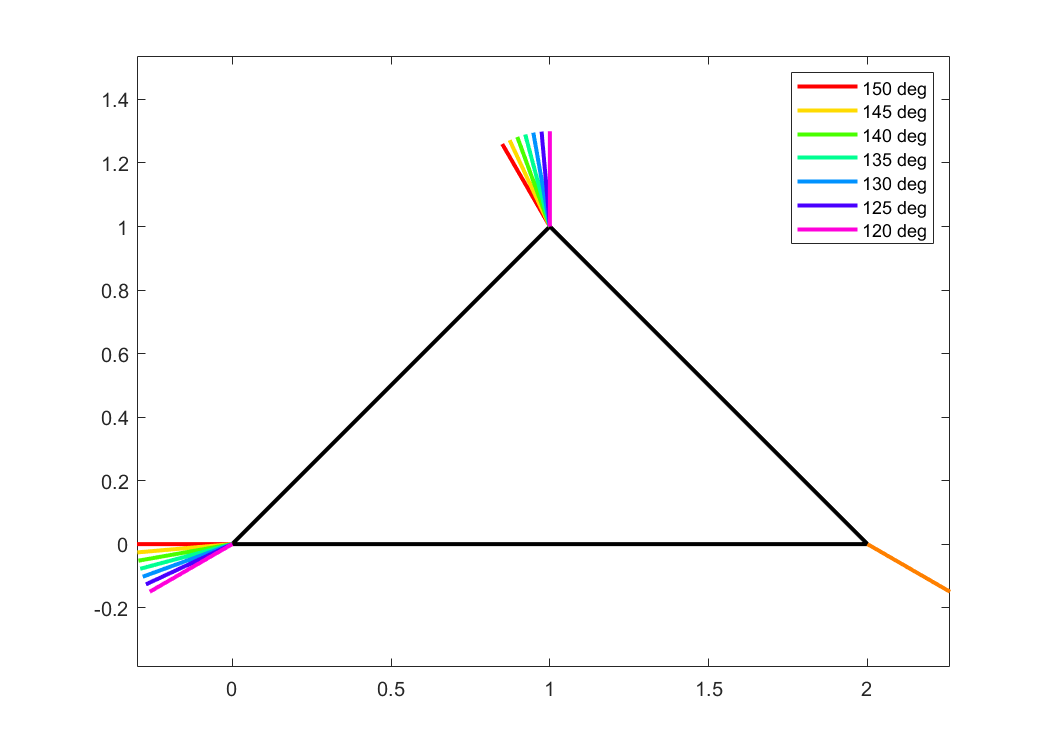


% Define triangle vertices
x = [0 1 2 0];
y = [0 1 0 0];

w=[150,145,140,135,130,125,120];
% Define length of side lines
L = 0.3;

for p=1:7
% Define angles for the three sides
theta1 = deg2rad(w(p)-120+90);
theta2 = deg2rad(-30);
theta3 = deg2rad(150-w(p)+180);
x2(p,:) = [x(2) x(2)+L*cos(theta1)];
y2(p,:) = [y(2) y(2)+L*sin(theta1)];
x4(p,:) = [x(1) x(1)+L*cos(theta3)];
y4(p,:) = [y(1) y(1)+L*sin(theta3)];
end

% Compute side line coordinates
x1 = x(1:2);
y1 = y(1:2);
x3 = [x(3) x(3)+L*cos(theta2)];
y3 = [y(3) y(3)+L*sin(theta2)];

colors = hsv(7);
% Plot triangle and side lines
f2=figure('Renderer', 'painters', 'Position', [10 10 700 500]);

plot(x,y,'k-','LineWidth',2);
hold on;
plot(x1,y1,'k-','LineWidth',2);
plot(x3,y3,'Color',[1, 0.5, 0],'LineWidth',2);
for p=1:7
    l1(p)=plot(x2(p,:),y2(p,:),'Color',colors(p,:),'LineWidth',2);
    
    plot(x4(p,:),y4(p,:),'Color',colors(p,:),'LineWidth',2);
end
hold off;
axis equal;

legend(l1,'150 deg','145 deg','140 deg','135 deg','130 deg','125 deg','120 deg')
exportgraphics(f2,'MooringAngles.pdf')

## Tensions

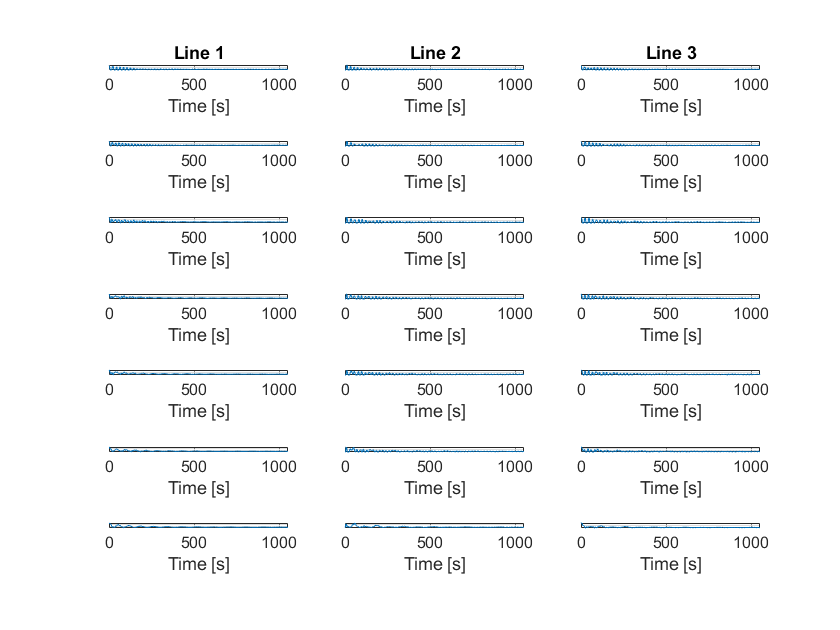

t120 = load('E:\Stuff\tensions/120.txt');
t120(:,1:(700))=[];
t125 = load('E:\Stuff\tensions/125.txt');
t125(:,1:(700))=[];
t130 = load('E:\Stuff\tensions/130.txt');
t130(:,1:(700))=[];
t135 = load('E:\Stuff\tensions/135.txt');
t135(:,1:(700))=[];
t140 = load('E:\Stuff\tensions/140.txt');
t140(:,1:(700))=[];
t145 = load('E:\Stuff\tensions/145.txt');
t145(:,1:(700))=[];
t150 = load('E:\Stuff\tensions/150.txt');
t150(:,1:(700))=[];

time=linspace(0,1050,2099);
col_titles = {'120 deg', 'Column 2', 'Column 3'};


figure()
subplot(7,3,1)
plot(time,t120(1,:));
grid on
xlabel('Time [s]')
ylabel('120 deg')
title('Line 1')
xlim([0 1050])

subplot(7,3,2)
plot(time,t120(2,:));
grid on
xlabel('Time [s]')
ylabel('120 deg')
title('Line 2')
xlim([0 1050])

subplot(7,3,3)
plot(time,t120(3,:));
grid on
xlabel('Time [s]')
ylabel('125 deg')
title('Line 3')
xlim([0 1050])

subplot(7,3,4)
plot(time,t125(1,:));
grid on
xlabel('Time [s]')
ylabel('125 deg')
xlim([0 1050])

subplot(7,3,5)
plot(time,t125(2,:));
grid on
xlabel('Time [s]')
ylabel('125 deg')
xlim([0 1050])

subplot(7,3,6)
plot(time,t125(3,:));
grid on
xlabel('Time [s]')
ylabel('125 deg')
xlim([0 1050])

subplot(7,3,7)
plot(time,t130(1,:));
grid on
xlabel('Time [s]')
ylabel('130 deg')
xlim([0 1050])

subplot(7,3,8)
plot(time,t130(2,:));
grid on
xlabel('Time [s]')
ylabel('130 deg')
xlim([0 1050])

subplot(7,3,9)
plot(time,t130(3,:));
grid on
xlabel('Time [s]')
ylabel('130 deg')
xlim([0 1050])

subplot(7,3,10)
plot(time,t135(1,:));
grid on
xlabel('Time [s]')
ylabel('135 deg')
xlim([0 1050])

subplot(7,3,11)
plot(time,t135(2,:));
grid on
xlabel('Time [s]')
ylabel('135 deg')
xlim([0 1050])

subplot(7,3,12)
plot(time,t135(3,:));
grid on
xlabel('Time [s]')
ylabel('135 deg')
xlim([0 1050])

subplot(7,3,13)
plot(time,t140(1,:));
grid on
xlabel('Time [s]')
ylabel('140 deg')
xlim([0 1050])

subplot(7,3,14)
plot(time,t140(2,:));
grid on
xlabel('Time [s]')
ylabel('140 deg')
xlim([0 1050])

subplot(7,3,15)
plot(time,t140(3,:));
grid on
xlabel('Time [s]')
ylabel('140 deg')
xlim([0 1050])

subplot(7,3,16)
plot(time,t145(1,:));
grid on
xlabel('Time [s]')
ylabel('145 deg')
xlim([0 1050])

subplot(7,3,17)
plot(time,t145(2,:));
grid on
xlabel('Time [s]')
ylabel('145 deg')
xlim([0 1050])

subplot(7,3,18)
plot(time,t145(3,:));
grid on
xlabel('Time [s]')
ylabel('145 deg')
xlim([0 1050])

subplot(7,3,19)
plot(time,t150(1,:));
grid on
xlabel('Time [s]')
ylabel('150 deg')
xlim([0 1050])

subplot(7,3,20)
plot(time,t150(2,:));
grid on
xlabel('Time [s]')
ylabel('150 deg')
xlim([0 1050])

subplot(7,3,21)
plot(time,t150(3,:));
grid on
xlabel('Time [s]')
ylabel('150 deg')
xlim([0 1050])



Means=[mean(t120(1,:)),mean(t120(2,:)),mean(t120(3,:));mean(t125(1,:)),mean(t125(2,:)),mean(t125(3,:));mean(t130(1,:)),mean(t130(2,:)),mean(t130(3,:));mean(t135(1,:)),mean(t135(2,:)),mean(t135(3,:));mean(t140(1,:)),mean(t140(2,:)),mean(t140(3,:));mean(t145(1,:)),mean(t145(2,:)),mean(t145(3,:));mean(t150(1,:)),mean(t150(2,:)),mean(t150(3,:))];
Maxs=[max(t120(1,:)),max(t120(2,:)),max(t120(3,:));max(t125(1,:)),max(t125(2,:)),max(t125(3,:));max(t130(1,:)),max(t130(2,:)),max(t130(3,:));max(t135(1,:)),max(t135(2,:)),max(t135(3,:));max(t140(1,:)),max(t140(2,:)),max(t140(3,:));max(t145(1,:)),max(t145(2,:)),max(t145(3,:));max(t150(1,:)),max(t150(2,:)),max(t150(3,:))];
Stds=[std(t120(1,:)),std(t120(2,:)),std(t120(3,:));std(t125(1,:)),std(t125(2,:)),std(t125(3,:));std(t130(1,:)),std(t130(2,:)),std(t130(3,:));std(t135(1,:)),std(t135(2,:)),std(t135(3,:));std(t140(1,:)),std(t140(2,:)),std(t140(3,:));std(t145(1,:)),std(t145(2,:)),std(t145(3,:));std(t150(1,:)),std(t150(2,:)),std(t150(3,:))];


## single

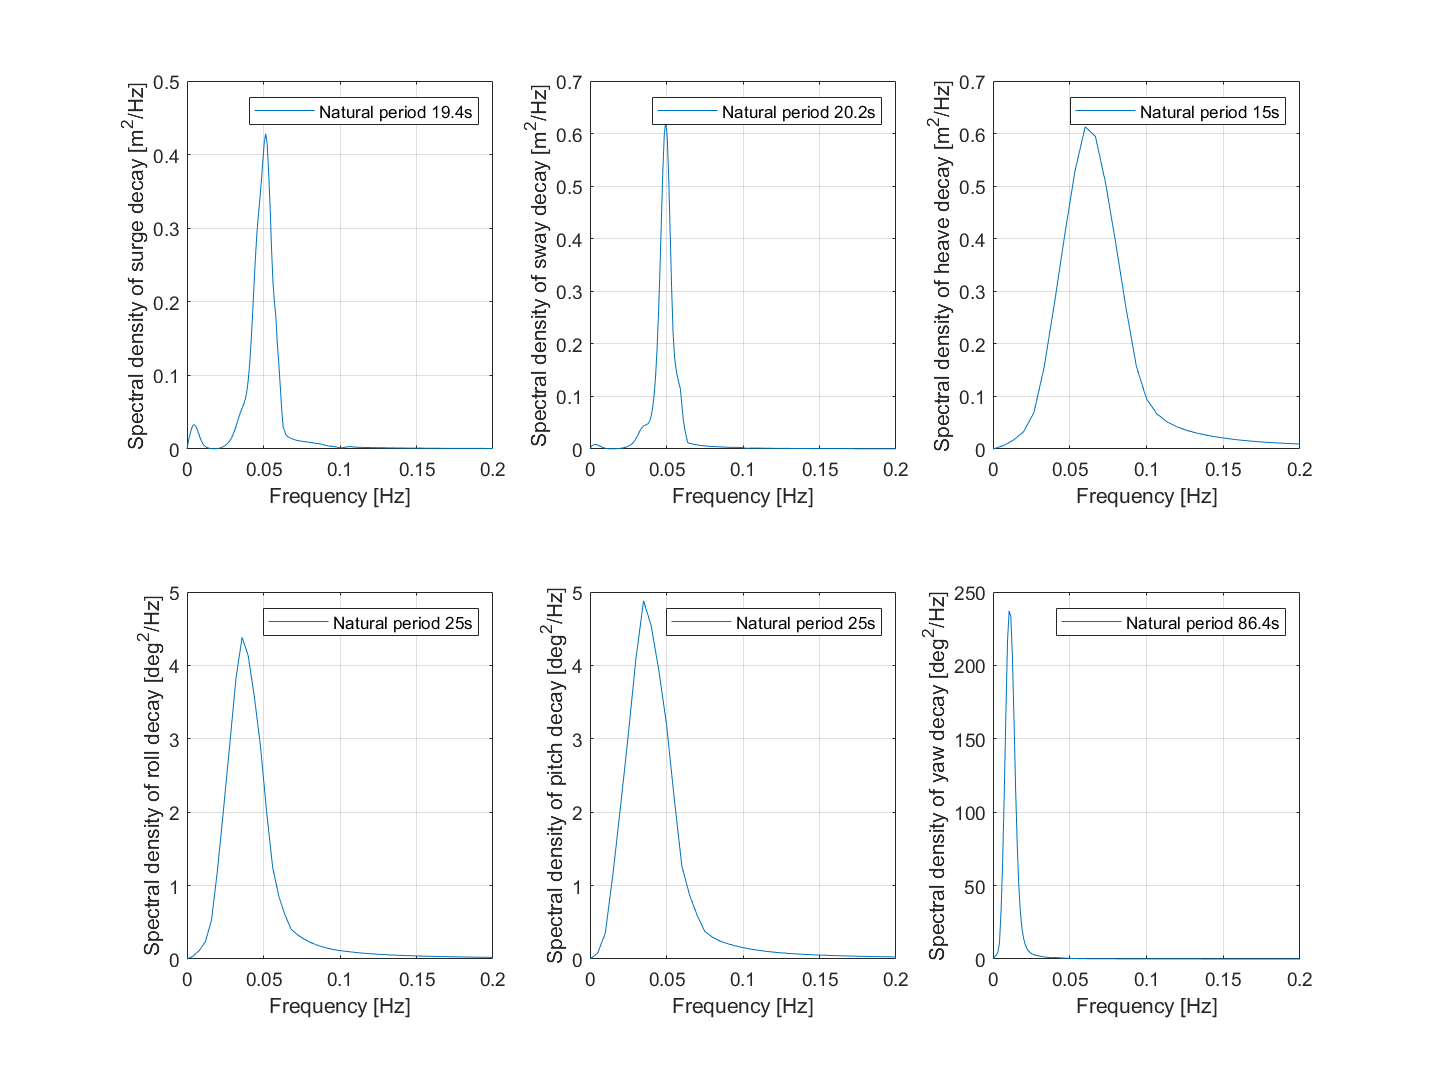

f1=figure('Renderer', 'painters', 'Position', [10 10 1200 900]);
subplot(2,3,1)
plot(fpsd_F1, smooth(psds_F1(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of surge decay [m^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerF1(1))) 's'])
xlim([0 0.2])

subplot(2,3,2)
plot(fpsd_F2, smooth(psds_F2(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of sway decay [m^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerF2(1))) 's'])
xlim([0 0.2])

subplot(2,3,3)
plot(fpsd_F3, smooth(psds_F3(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of heave decay [m^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerF3(1))) 's'])
xlim([0 0.2])

subplot(2,3,4)
plot(fpsd_M1, smooth(psds_M1(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of roll decay [deg^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerM1(1))) 's'])
xlim([0 0.2])

subplot(2,3,5)
plot(fpsd_M2, smooth(psds_M2(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of pitch decay [deg^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerM2(1))) 's'])
xlim([0 0.2])

subplot(2,3,6)
plot(fpsd_M3, smooth(psds_M3(1,:)))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of yaw decay [deg^2/Hz]')
legend( ['Natural period ' num2str(cell2mat(NatPerM3(1))) 's'])
xlim([0 0.2])

exportgraphics(f1,'FloaterDecay.pdf')